# Actividad 1: Velocidades lineales y angulares

#### Fundamentación de Robótica

Fernando Estrada Silva // A01736094

**Objetivo **

Obtener el vector de velocidades lineales y angulares para la configuración de un robot manipulador de 2 grados de libertad. 

**Introducción **

Dentro del contexto de la configuración para un robot con 2 grados de libertdad, la velocidad lineal se refiere a la tasa de cambio instantáneo de la posición del extremo del eslabón en una trayectoria recta. La velocidad lineal está relacionada con coordenadas cartesiadas dentro del espacio tridimensional, por lo que implica una variación de posición con respecto a la velocidad. Para construir el vector de velocidad lineal, el análisis de movimiento debe realizarse para cada una de las 3 variables (x,y,z). 

Del otro lado, la velocidad angular corresponde a la rapidez con la que el extremo del eslabón del robot rota alrededor de su propio eje. Por lo tanto, esta velocidad se referiere al cambio instantáneo del ángulo de los grados de libertad del robot. La coordinación adecuada entre la velocidad lineal y angular es crucial para lograr trayectorias y movimientos fluidos y eficientes en el entorno operativo del robot.

**Metodología **

La actividad consiste en realizar el análisis pertinente para obtener la velocidad lineal y rotacional para un robot de 2 grados de libertad que únicamente tiene rotación en el eje Z. El diagrama de movimiento se describe en la siguiente imagen. 

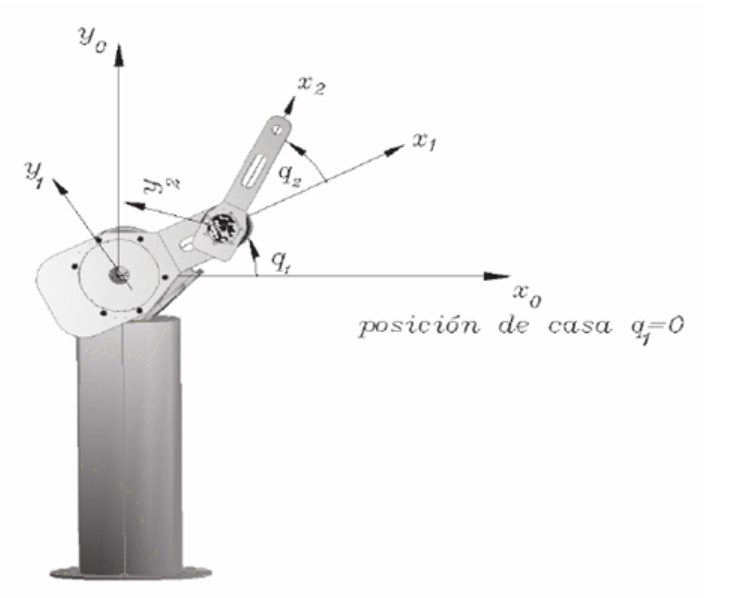

Para desarrollar la actividad, se utilizará como referencia el código de matlab proporcionado por el profesor, el cual realiza el mismo análisis pero para un péndulo simple. Para dar solución a la nueva situación se propone la siguiente metodología: 

Considerando que se solicita un robot con 2 grados de libertad, deben agregarse 2 nuevas variables simbólicas: angulo theta2 y longitud del eslabón 2, correspondientemente. 

%Declaración de variables simbólicas (No tienen un valor específico)
syms th1(t) l1 t  th1(t) l2

Asi mismo, se le debe agregar un nuevo 0 al arreglo de junta rotacional en virtud del otro grado de libertad, así como el valor simbólico del angulo th2 en el vector de coordenadas articulares. 

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

%Creamos el vector de coordenadas articulares
Q= [th1 th2]; 
disp('Coordenadas articulares');

Coordenadas articulares


pretty (Q);

(th1(t), th2(t))




%Creamos el vector de velocidades articulares
Qp= diff(Q, t); %Utilizo diff para derivadas cuya variable de referencia no depende de otra: ejemplo el tiempo
disp('Velocidades articulares');

Velocidades articulares


pretty (Qp);

/  d          d        \
| -- th1(t), -- th2(t) |
\ dt         dt        /



%Número de grado de libertad del robot
GDL= size(RP,2); %***Siempre se coloca 2, ya que indica la dimensión de las columnas
GDL_str= num2str(GDL);%Convertimos el valor numérico a una cadena de carácteres tipo string



Ahora, en la siguiente sección se encuentran los cambios necesarios para adaptar el programa a un robot de 2 grados de libertad. Considerando que el robot se encuentra rotando únicamente sobre el eje z, y recurriendo a la matriz de rotación: 

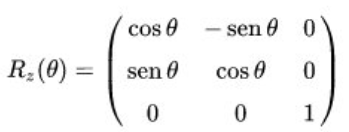 

Del otro lado, la matriz de posición puede describirse como: 

Para configurar tanto la rotación y posición del nuevo grado de libertad, basta con duplicar la sección que incluye la matriz de rotación, cambiando  parámetros tales como la longitud 2 del eslabón y el ángulo para el segundo grado de libertad. 


%Articulación 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [l1*cos(th1) ;
           l1*sin(th1);
                     0];%*** Vector de posición indexado por página

%Matriz de rotación de la articulación 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0; %*** Análisis de robot péndulo
           sin(th1)  cos(th1)  0;
           0         0         1];

%Articulacion 2
%Posicion de la junta 2 con respecto a 0 
P(:,:,2)= [l2*cos(th2);
           l2*sin(th2);
                     0];%*** Vector de posición indexado por página

%Matriz de rotación de la articulación 2 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0; %*** Análisis de robot péndulo 
           sin(th2)  cos(th2)  0;
           0         0         1];

Posteriormente, se inicializan las matrices para almacenar matrices de transformación homogénea local y global. 

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);%****

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);%*****

%Inicializamos los vectores de posición vistos desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); %*****

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL);

Para imprimir las matrices de forma presentable y con fines de optimizar los cambios al programa, se implementa un ciclo for para recorrer todos los grados de libertad de cualquier robot. Para cada uno, se imprime su matriz de transformación local. Nótese que se utiliza la función pretty para imprimir adecuadamente y con la forma más simplificada posible. 

%El ciclo imprime dos veces cada Matriz de Transformación local y global
for i = 1:GDL
    i_str= num2str(i);
    %Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

    %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);  %Caso específico cuando i=1 nos marcaría error en try
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i));

%Obtenemos la matriz de rotación "RO "y el vector de translación PO de la
%matriz de transformación Homogénea global T(:,:,GDL)
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2


/ #2, -#1, 0, l1 cos(th1(t)) + l2 #2 \
|                                    |
| #1,  #2, 0, l1 sin(th1(t)) + l2 #1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




/ cos(th1(t) + th2(t)), -sin(th1(t) + th2(t)), 0 \
|                                                |
| sin(th1(t) + th2(t)),  cos(th1(t) + th2(t)), 0 |
|                                                |
\           0,                    0,           1 /



/ l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                          |
| l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                          |
\                     0                    /



Para obtener las mas matrices jacobianas, se deben calcular las derivadas parciales para cada eje tridimensional. A diferencia del ejemplo anterior, ahora se incluyen las parciales también con respecto al segundo ángulo del otro grado de libertad. 

%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial



%Derivadas parciales de x respecto a th1 
Jv11= functionalDerivative(PO(1,1,GDL), th1);
%Derivadas parciales de y respecto a th1 
Jv21= functionalDerivative(PO(2,1,GDL), th1);
%Derivadas parciales de z respecto a th1 
Jv31= functionalDerivative(PO(3,1,GDL), th1);

%Derivadas parciales de x respecto a th1 
Jv12= functionalDerivative(PO(1,1,GDL), th2);
%Derivadas parciales de y respecto a th1 
Jv22= functionalDerivative(PO(2,1,GDL), th2);
%Derivadas parciales de z respecto a th1 
Jv32= functionalDerivative(PO(3,1,GDL), th2);


%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11;
              Jv21;
              Jv31]);
pretty(jv_d);

/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)) \
|                                            |
|  l1 cos(th1(t)) + l2 cos(th1(t) + th2(t))  |
|                                            |
\                      0                     /




%Calculamos el jacobiano lineal y angular de forma analítica
%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Finalmente, se imprimen de forma simplificada las matrices obtenidas, tales como el jacobiano de forma analítica, jacobiano angular de forma analítica, la velocidad lineal y angular. Los resultados se muestran a continuación. 

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)),                    #1                    \
|                                                                                      |
|                     #1,                     l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                                                                      |
\                      0,                                         0                    /

where

   #1 == l1 cos(th1(t)) + l2 cos(th1(t) + th2(t))




disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                             |
| 0, l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                             |
\ 1,                     0                    /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ _________      _________    \
|  d              d           |
| -- th2(t) #1 - -- th1(t) #2 |
| dt             dt           |
|                             |
| _________      _________    |
|  d              d           |
| -- th1(t) #1 + -- th2(t) #2 |
| dt             dt           |
|                             |
\              0              /

where

   #1 == l1 cos(th1(t)) + l2 cos(th1(t) + th2(t))

   #2 == l1 sin(th1(t)) + l2 sin(th1(t) + th2(t))




disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ _________                                            \
|  d                                                   |
| -- th2(t) (l1 cos(th1(t)) + l2 cos(th1(t) + th2(t))) |
| dt                                                   |
|                                                      |
| _________                                            |
|  d                                                   |
| -- th2(t) (l1 sin(th1(t)) + l2 sin(th1(t) + th2(t))) |
| dt                                                   |
|                                                      |
|                       _________                      |
|                        d                             |
|                       -- th1(t)                      |
\                       dt                             /

